# Chapter 4 Exercise Solutions

#### Exercise 4.1

A = [0, 0, 0, 0, 0 ; 
    1/4, 0, 0, 0, 0 ;
    1/2, 0, 0, 0, 0 ;
    0, 1/2, 1/4, 0, 0 ;
    0, 1/6, -1/3, 1/6, 0];
b = [-1 ; 2/3 ; -1/3 ; 2/3 ; 1];
e = ones(5, 1);

for k = 0 : 5
    rats(b' * A^k * e)
end

ans = '       1      '

ans = '      1/2     '

ans = '      1/6     '

ans = '      1/24    '

ans = '       0      '

ans = '       0      '


$$R(z) = 1 + z + \frac{1}{2}z^2 + \frac{1}{6}z^3 + \frac{1}{24}z^4$$


#### Exercise 4.2

A = [7/24, -1/24 ;
     13/24, 5/24 ];
ebT = [1/2, 0 ;
        0, 1/2];

P = @(z) det(eye(2) - z * A + z * ebT);
Q = @(z) det(eye(2) - z * A);

syms z
R = P(z) / Q(z)

$$R = \frac{\frac{z^{2}}{12}+\frac{z}{2}+1}{\frac{z^{2}}{12}-\frac{z}{2}+1}$$

solve(Q(z))

$$ans = \left(\begin{array}{c} 3-\sqrt{3}\,\mathrm{i}\\ 3+\sqrt{3}\,\mathrm{i} \end{array}\right)$$

E = Q(1i * y) * Q(-1i * y) - P(1i * y) * P(-1i * y)

$$E = 0$$

#### Exercise 4.3

A = [1/4, 1/4 - sym(sqrt(3)/6) ;  
     1/4 + sym(sqrt(3)/6), 1/4 ];
ebT = [1/2, 0 ; 
        0, 1/2];

P = @(z) det(eye(2) - z * A + z * ebT);
Q = @(z) det(eye(2) - z * A);

syms z
R = P(z) / Q(z)

$$R = \frac{\frac{z^{2}}{12}+\frac{z}{2}+1}{\frac{z^{2}}{12}-\frac{z}{2}+1}$$

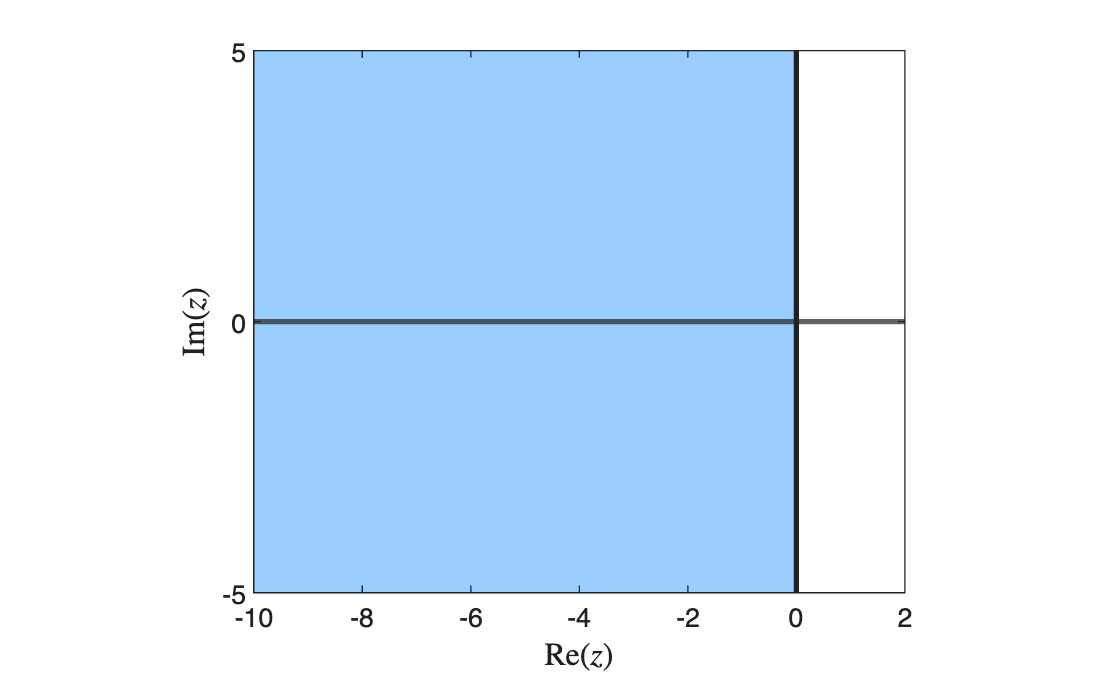

% Generate z values
xmin = -10;
xmax = 2;
ymin = -5;
ymax = 5;
[X, Y] = meshgrid(linspace(xmin, xmax, 200), linspace(ymin, ymax, 200));
Z = X + Y * 1i;

% Define stability function 
R = (1 + 1/2 * Z + 1/12 * Z.^2) ./ (1 - 1/2 * Z + 1/12 * Z.^2);

% Plot stability region
contourf(X, Y, abs(R), [0, 1], LineWidth=2)
xline(0, LineWidth=2)
yline(0, LineWidth=2)
colormap([153, 204, 255 ; 255, 255, 255] / 255)
axis equal
axis([xmin, xmax, ymin, ymax])
xlabel("$\mathrm{Re}(z)$", FontSize=12, Interpreter="latex")
ylabel("$\mathrm{Im}(z)$", FontSize=12, Interpreter="latex")

#### Excercise 4.4

A = [-20, 1 ;
     0, 500];

eig(A)

ans =    -20
   500


The eigenvalues are $\lambda_1 = -20$ and $\lambda_2 = -500$ so the stiffness ratio is


$$S = \frac{-500}{-20} = 25.$$


The stability function for the Euler method is $R(z) = 1 + z = 1 + h \lambda$. For stability, $|1 + h \lambda| \leq 1$. 

For $\lambda_1$, $|R(-25 h)| = |1 - 25(0.05)| = 0 < 1$ so is stable.

For $\lambda_2$, $|R(-500 h)| = |1 - 500(0.05)| = 24 > 1$ so is unstable.